# Grid of cells (2DOF)

clear; close all; clc;
set_env;
addpath("2DOF\");
load('2DOF\cell_2dof_pstrain.mat')
load('2DOF\cell_2dof_pstress.mat')
load('2DOF\res_2dof_pstrain.mat')

% Data --------------------------------------------------------------
% Constants

% Symbolic variables ------------------------------------------------
% Physical properties
syms x P_t f d p_atm p
% t_f(x) armature distance at a certain xsi

syms l_0

% Physical quantities
syms V


## Single cell quantites

pstrain = sstrain2(pstrain_2dof, 'PSTRAIN');
x_range_ref = res_2dof_pstrain{end}.x_range_ref;
C = pstrain.C1;


x_min = x_range_ref(1);
x_max = double(0.3 * sdata2(l_0));
x_range = x_min:1e-5:x_max;
x_range_norm = double(x_range / sdata2(l_0));
Uel_xmax = interp1(x_range_ref, res_2dof_pstrain{end}.Uel_xmax, x_range);
uel_xmax = interp1(x_range_ref, res_2dof_pstrain{end}.uel_xmax, x_range);
F_el = interp1(x_range_ref, res_2dof_pstrain{end-1}.int_F, x_range);
max_uel = max(uel_xmax);

myfig(1, "U_{el} and u_{el}");

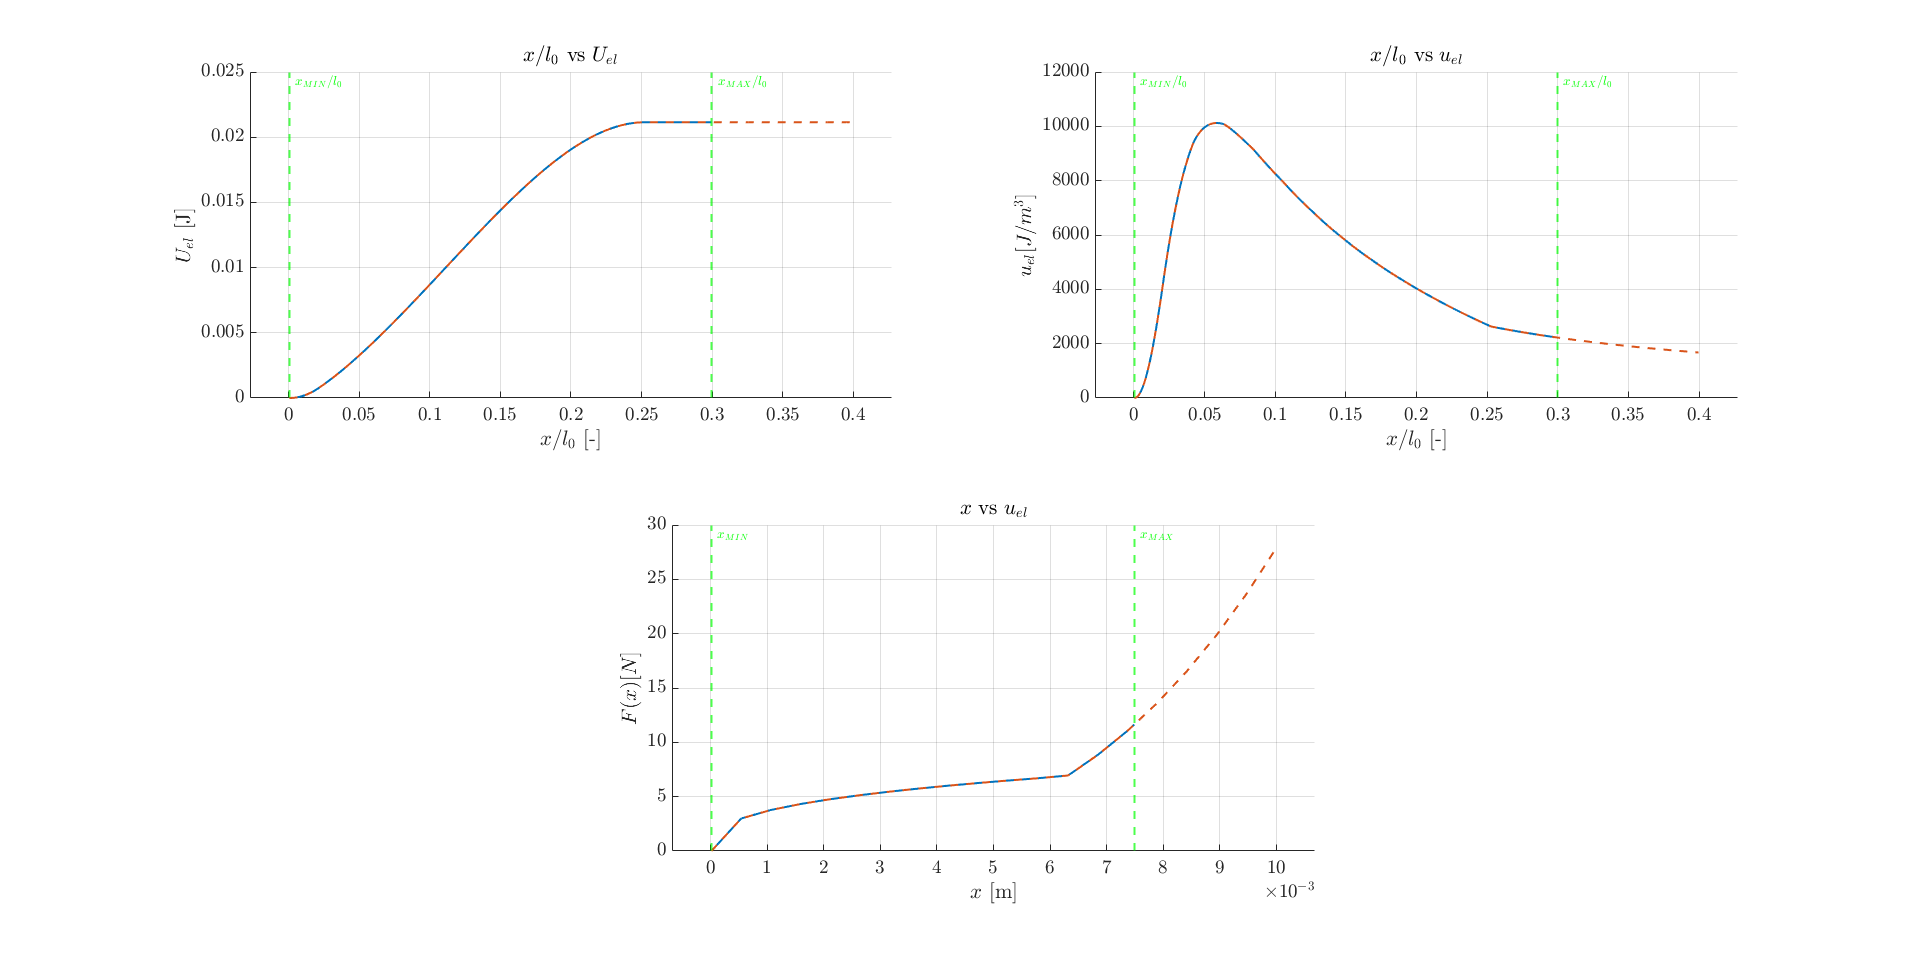

subplot(2,2,1); hold on
plot(x_range_norm, Uel_xmax)
plot(x_range_ref / sdata2(l_0), res_2dof_pstrain{end}.Uel_xmax, '--')
plot_xminmax(x_range_norm(1), x_range_norm(end), "$x_{MIN} / l_0$", "$x_{MAX} / l_0$")
addlabels("$x / l_0$ [-]", "$U_{el}$ [J]", "$x / l_0$ vs $U_{el}$")
xlim("padded")

subplot(2,2,2); hold on
plot(x_range_norm, uel_xmax)
plot(x_range_ref / sdata2(l_0), res_2dof_pstrain{end}.uel_xmax, '--')
plot_xminmax(x_range_norm(1), x_range_norm(end), "$x_{MIN} / l_0$", "$x_{MAX} / l_0$")
addlabels("$x / l_0$ [-]", "$u_{el} [J/m^3]$", "$x / l_0$ vs $u_{el}$")
xlim("padded")

subplot(2,2,3.5); hold on
plot(x_range, F_el)
plot(x_range_ref, res_2dof_pstrain{end-1}.int_F, '--')
plot_xminmax(x_range(1), x_range(end))
addlabels("$x$ [m]", "$ F(x) [N]$", "$x$ vs $u_{el}$")
xlim("padded")

## Grid design

syms m_a
m_a = double(sdata2(solve(P_t == max_uel * f * m_a, m_a)))

m_a =   49.398873738560944


N = 500

N =    500


NrNc = [divisors(N)',N./divisors(N)'];
N_r = NrNc(length(NrNc) / 2, 1)

N_r =     20


N_c = NrNc(length(NrNc) / 2, 2)

N_c =     25



x_t = N_r * x;
x_t0 = N_r * x_range(ceil(end/2));
eq_pFel = (p - p_atm) * pi / 4 * d^2 == F_el(x_range == x_range(ceil(end/2))) * N / N_r;
p_0 = double(sdata2(solve(eq_pFel, p)))

p_0 =      1.013323644168282e+05
